## get datacube

% file path
hdr_path_name = 'D:\datasets\randomRAMAN\100ftftf.hdr';
raw_path_name = 'D:\datasets\randomRAMAN\100ftftf.raw';

% get dimensions and waves
info = get_info(hdr_path_name);
[samples, lines, bands, wavelengths] = get_dimensions(info)

samples = 1024

lines = 638

bands = 1024

wavelengths = 	1.0e+03 *

    0.7321    0.7324    0.7327    0.7329    0.7332    0.7334    0.7337    0.7340    0.7342    0.7345    0.7347    0.7350    0.7353    0.7355    0.7358    0.7360    0.7363    0.7366    0.7368    0.7371    0.7373    0.7376    0.7378    0.7381    0.7384    0.7386    0.7389    0.7391    0.7394    0.7397    0.7399    0.7402    0.7404    0.7407    0.7410    0.7412    0.7415    0.7417    0.7420    0.7423    0.7425    0.7428    0.7430    0.7433    0.7436    0.7438    0.7441    0.7443    0.7446    0.7449



% raman shift
raman_shift = 10^7/785 - 10^7./wavelengths;

% get datacube

tic
rawdata = get_rawdata(raw_path_name);
rawcube0 = reshape(rawdata, [samples, bands, lines]); % contrast order to python
rawcube = permute(rawcube0, [3, 1, 2]);
toc

历时 1.248264 秒。


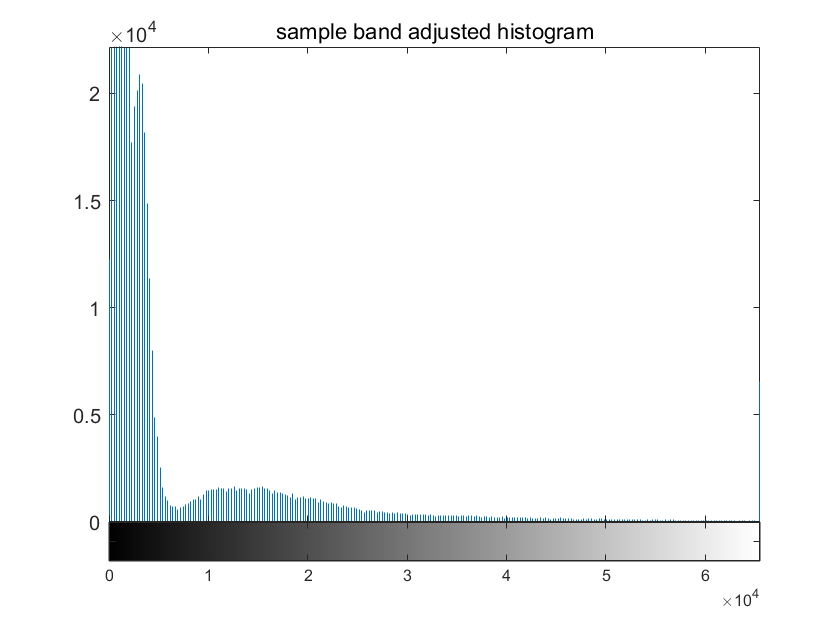

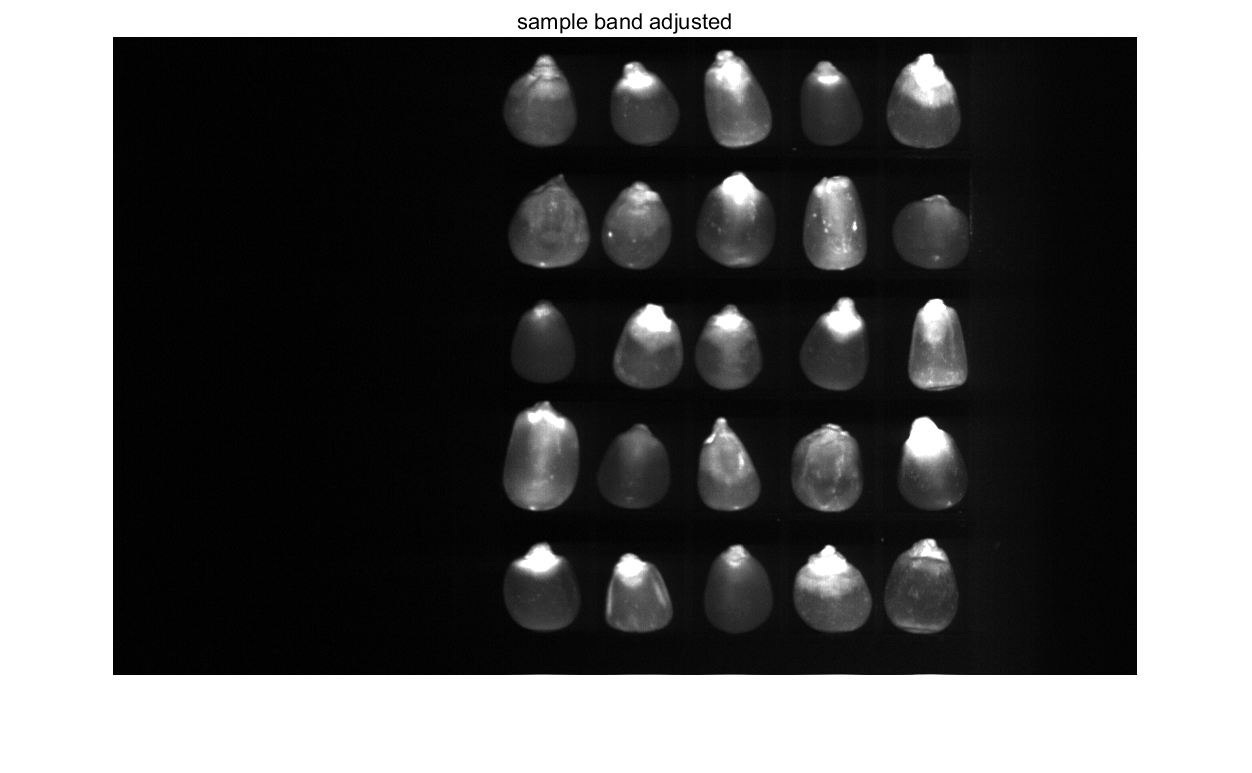

% band display  
display_band(rawcube, 500);

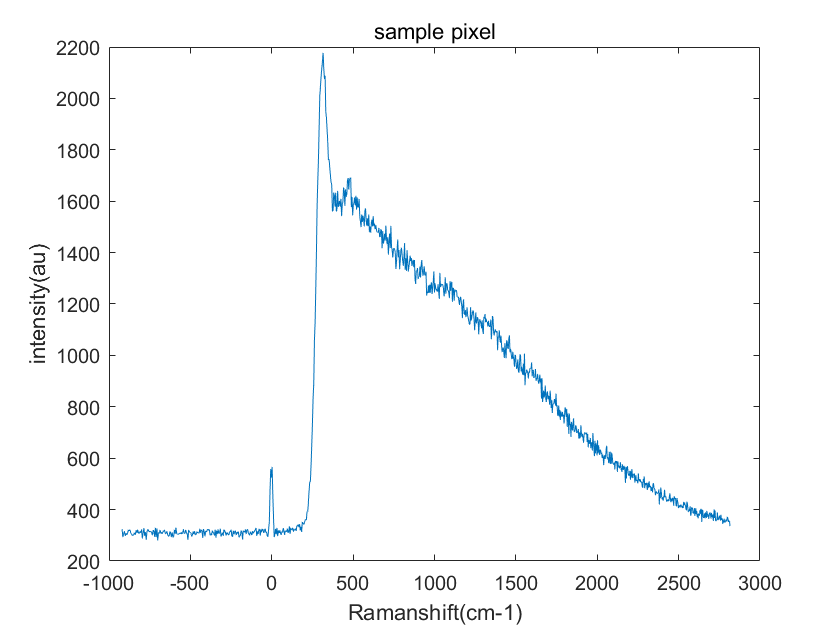


% pixel display 
display_pixel(rawcube, raman_shift, 300, 630);

% effective raman shift 
[~, p1] = min(abs(raman_shift - 400));
[~, p2] = min(abs(raman_shift - 1800));
effshift = raman_shift(p1:p2);

% define effcube
effcube = rawcube(:, 350:915, p1:p2);
efflines = size(effcube, 1);
effsamples = size(effcube, 2);
effbands = size(effcube, 3);

## mask and roi

% effective band for mask
[~, b] = min(abs(effshift - 477))

b = 20

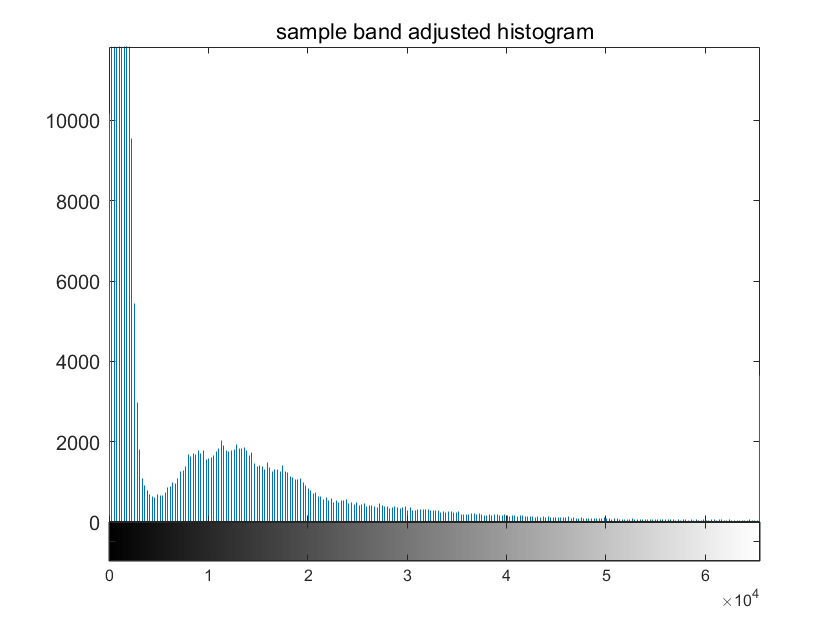

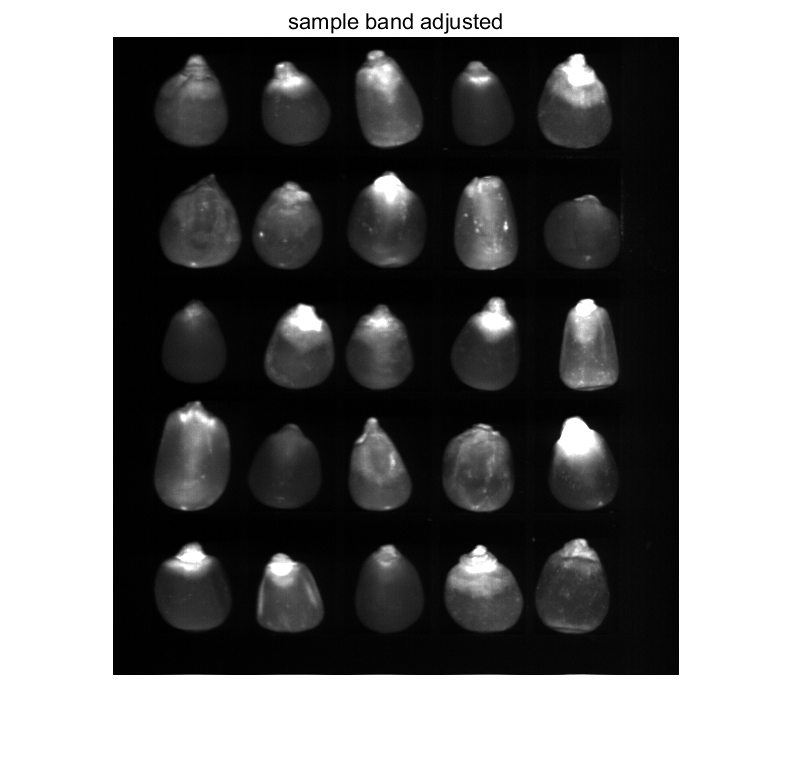

display_band(effcube, b);

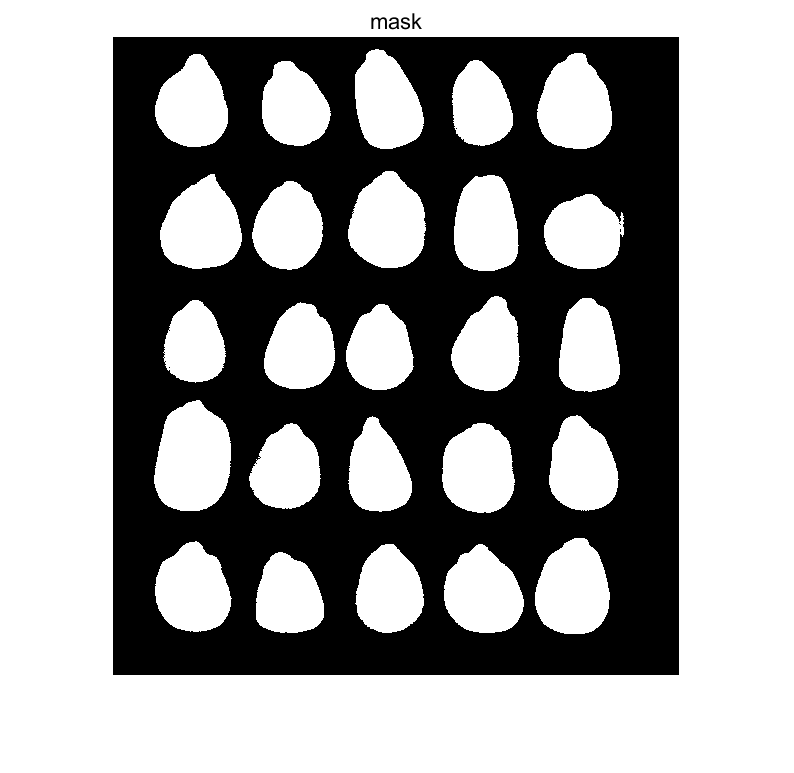

% mask 
bw = get_mask(effcube, b);
figure; imshow(bw); title('mask')

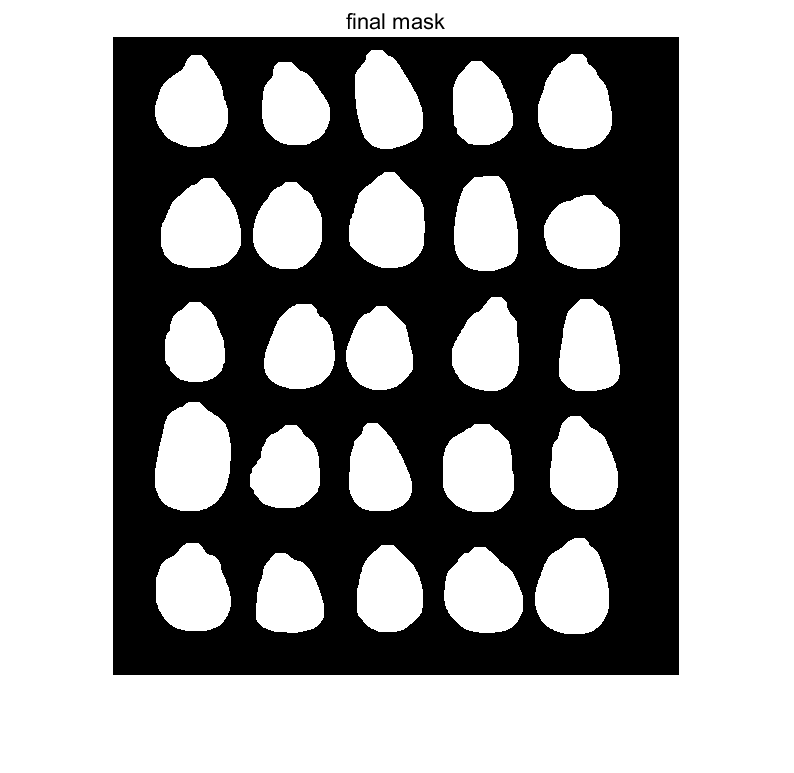

% morphology
se1 = strel('disk', 8);
se2 = strel('disk', 1);
bw_final = imopen(imclose(imopen(bw, se1), se2), se2);
bw_final = bwareaopen(bw_final, 1000, 8);     
figure; imshow(bw_final); title('final mask')

% roi average data 
tic
[avedata, unsorted_data, datalabel] = get_ave_spec(effcube, bw_final);
toc

历时 21.820455 秒。


avedata(1:10, :)         % 按照位置从上到下排列

ans = 	1.0e+03 *

    0.9694    0.9713    0.9694    0.9726    0.9685    0.9712    0.9702    0.9734    0.9736    0.9774    0.9779    0.9771    0.9769    0.9754    0.9758    0.9800    0.9866    0.9959    1.0047    1.0102    1.0063    0.9981    0.9900    0.9824    0.9765    0.9728    0.9690    0.9657    0.9620    0.9619    0.9578    0.9582    0.9532    0.9532    0.9491    0.9449    0.9434    0.9430    0.9406    0.9420    0.9419    0.9416    0.9435    0.9439    0.9436    0.9437    0.9425    0.9418    0.9392    0.9399
    1.1913    1.1947    1.1939    1.1981    1.1920    1.1956    1.1954    1.2000    1.2016    1.2074    1.2085    1.2071    1.2051    1.2028    1.2029    1.2111    1.2241    1.2413    1.2575    1.2657    1.2598    1.2465    1.2326    1.2206    1.2105    1.2046    1.1992    1.1953    1.1899    1.1914    1.1866    1.1865    1.1803    1.1801    1.1734    1.1690    1.1662    1.1651    1.1635    1.1655    1.1667    1.1668    1.1692    1.1705    1.1709    1.1706    1.1680    1.1666 

unsorted_data(1:10, :)   % 按照颜色从深到浅排列

ans = 	1.0e+03 *

    1.1812    1.1818    1.1799    1.1830    1.1787    1.1805    1.1791    1.1815    1.1835    1.1872    1.1866    1.1872    1.1847    1.1831    1.1828    1.1892    1.1958    1.2054    1.2154    1.2203    1.2154    1.2078    1.1977    1.1894    1.1834    1.1777    1.1736    1.1700    1.1650    1.1643    1.1602    1.1605    1.1550    1.1541    1.1495    1.1446    1.1421    1.1414    1.1386    1.1388    1.1389    1.1395    1.1407    1.1397    1.1397    1.1386    1.1365    1.1359    1.1322    1.1330
    1.4615    1.4651    1.4608    1.4670    1.4602    1.4640    1.4626    1.4673    1.4682    1.4747    1.4743    1.4727    1.4714    1.4693    1.4686    1.4764    1.4865    1.5002    1.5148    1.5237    1.5164    1.5069    1.4932    1.4826    1.4737    1.4673    1.4633    1.4570    1.4509    1.4524    1.4454    1.4472    1.4411    1.4405    1.4342    1.4283    1.4241    1.4248    1.4228    1.4236    1.4230    1.4237    1.4256    1.4248    1.4243    1.4239    1.4208    1.4205 

datalabel               

datalabel =      5     6    13    20    22
     3     7    11    19    24
     4     8    15    16    25
     2    10    12    18    23
     1     9    14    17    21


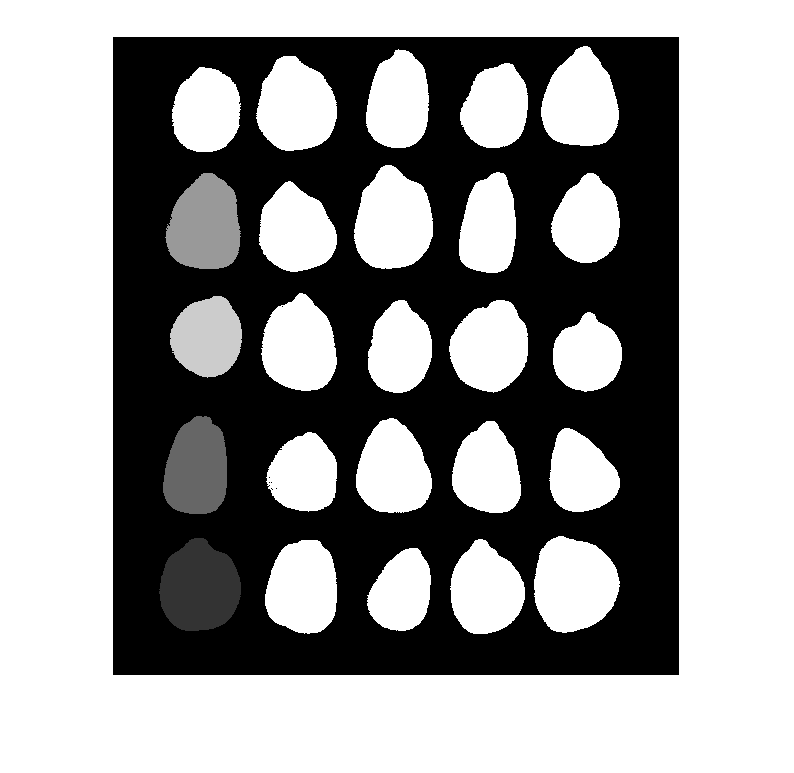

% 位置即位置，值即颜色，第一个位置找5度颜色，第二个位置找3度颜色
imshow((label-0)*0.2)   